% clear
% clc

system("make clean -f .\Makefile");

rm -f *.exe
rm -f *.exp
rm -f *.lib
rm -f *.txt


system("make main -f .\Makefile");

g++ -Wall -Wpedantic -O2 sensingArray.cpp -o sensingArray.exe


system(".\sensingArray.exe");

fp_info = fopen("info.txt","r");
N = str2double(fgetl(fp_info));
M = str2double(fgetl(fp_info));
fclose(fp_info);

x_ = load("x.txt");

Dv_ = load("Dv.txt") * 1e6;
Dv_max = max(Dv_);
Dv_min = min(Dv_);
v_points = readmatrix("v_Points.txt");

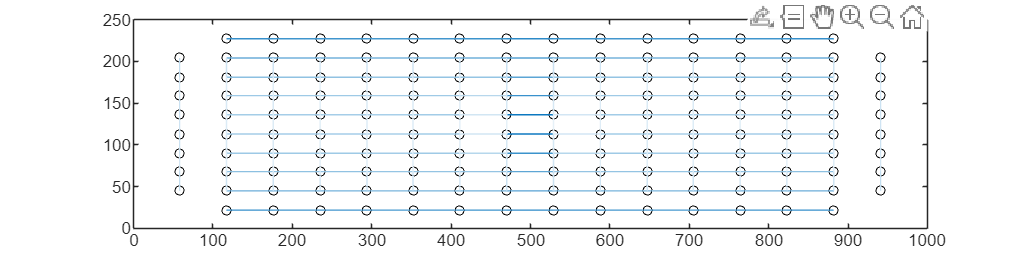

figure("Position",[0,0,N,M])
sz = 20;
scatter(v_points(:,1),v_points(:,3),sz,'ko')
hold on
scatter(v_points(:,2),v_points(:,4),sz,'ko')

for i = 1:length(Dv_)
    v1.x = v_points(i,1);
    v2.x = v_points(i,2);
    v1.y = v_points(i,3);
    v2.y = v_points(i,4);
    color = sky();
    color_ind = (Dv_(i) - Dv_min) / (Dv_max - Dv_min);
    color_ind = round(color_ind * length(Dv_) + 1);
    plot([v1.x v2.x],[v1.y v2.y],Color=color(color_ind,:))
end

hold off
box on
xlim([0,N])
ylim([0,M])

scan = 59

scan = 59

x = x_(:,scan);
Dv = Dv_(scan) % [μV]

Dv = 44.9405

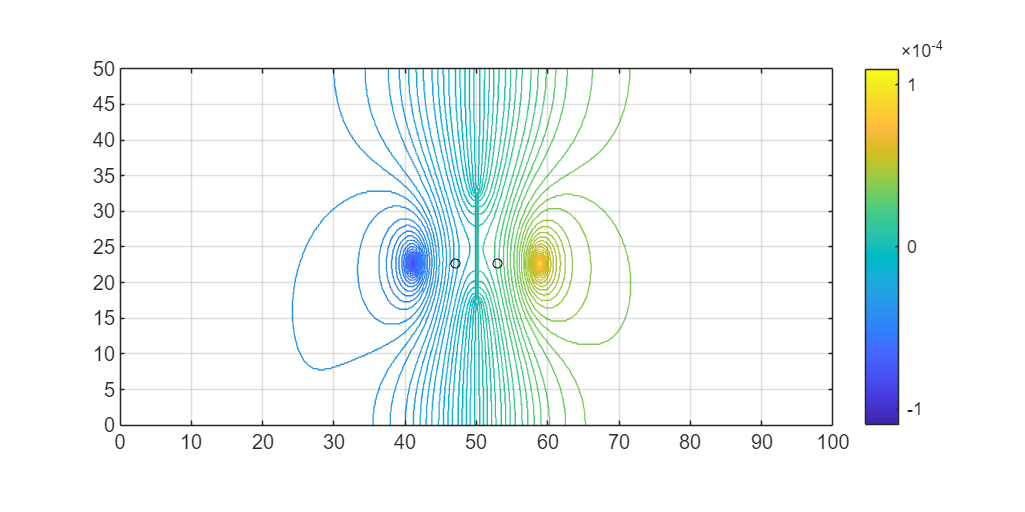

v1.x = v_points(scan,1);
v2.x = v_points(scan,2);
v1.y = v_points(scan,3);
v2.y = v_points(scan,4);

phi = zeros(M,N);
for i = 1:N
    for j = 1:M
        phi(j,i) = x(i + N * (j-1));
    end
end

% psi = zeros(M,N);
% for i = 3:N
%     for j = 3:M-1
%         psi(j,i) = 1/3 * (4*psi(j-1,i) - psi(j-2,i) + (3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2)));
%         psi(j,i) = min(psi(j,i),1e-7);
%         psi(j,i) = max(psi(j,i),-1e-7);
%     end
% end

figure("Position",2*[0,0,1000,500]);
X_range = linspace(0,100,size(phi,2));
Y_range = linspace(0,50,size(phi,1));
Dx = X_range(2) - X_range(1);
Dy = Y_range(2) - Y_range(1);
contour(X_range,Y_range,phi,100, ...
    'LineStyle',"-", ...
    "fill","off")

hold on
sz = 20;
scatter(Dx*v1.x,Dy*v1.y,sz,'ko')
scatter(Dx*v2.x,Dy*v2.y,sz,'ko')
% scatter(Dx*v3.x,Dy*v3.y,sz,'ko')
% scatter(Dx*v4.x,Dy*v4.y,sz,'ko')
xticks(X_range(1) : X_range(end)/10 : X_range(end))
yticks(Y_range(1) : Y_range(end)/10 : Y_range(end))
hold off
grid on
axis equal
colorbar()